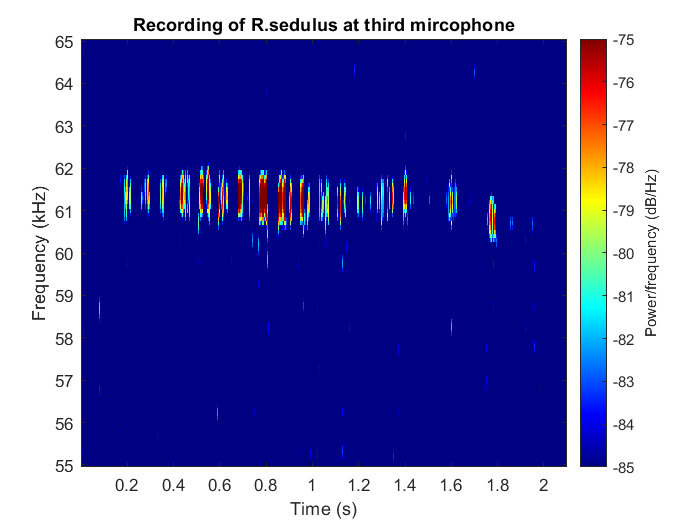

%plotting for the presentation
micData = timetable2table(micArrayData);

%sampling frequency
Fs = 500000;

%first figure
figure(1)
clf
spectrogram(table2array(micData(Fs*3.1:Fs*5.2,4)),1000,50,55*1e3:100:65*1e3,Fs,'yaxis');
title("Recording of R.sedulus at third mircophone")
colormap('jet')
caxis([-85 -75])

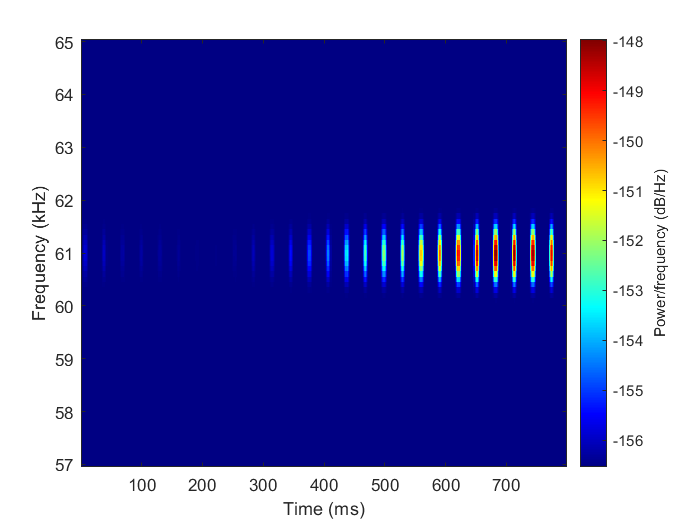

%set the mic data
micData = fullESMSolution(1).geomSolutions;

%set the sampling frequency
Fs = 500000;

%plot the array geometry
figure(2)
clf
spectrogram(fullESMSolution(1).geomSolutions(5,1.2*Fs:2*Fs),1000,50,57*1e3:100:65*1e3,Fs,'yaxis');
colormap('jet')

%caxis([-85 -50])
%set(gca,'visible','off')

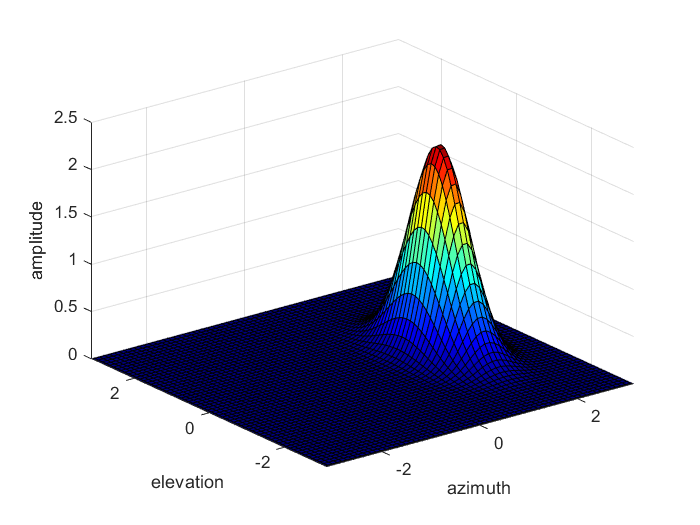

singleSourceVars = struct("Location",[0,0,0],"Direction",[1,0,0]);

%create the beam pattern visualization
[beamPatternSph, beamPatternLin] = generateBeamPatternBasic(singleSourceVars,fullInputStruct.beamPatternData(1).beamData);

%surf it
surf(beamPatternSph.phi,beamPatternSph.theta,beamPatternSph.amplitude)
xlim([-pi pi])
ylim([-pi pi])
xlabel("azimuth")
ylabel("elevation")
zlabel("amplitude")